% t = readtable("history_data/characteristic_bolete.h5_history.csv")
% 
% f = plotCurves(t, "Characteristic 512x512 GoogLeNet");
% saveas(f,"plots/characteristic_loss_512.png")

files = dir("history_data/*_history.csv")

files = 4×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


names = string.empty(length(files), 0);
for i = 1:length(files)
     names(i) = files(i).name;
end
names = names'

names = 4×1 string array
    "characteristic_bolete.h5_history.csv"
    "characteristic_bolete_lowres.h5_history.csv"
    "direct_bolete.h5_history.csv"
    "direct_bolete_lowres.h5_history.csv"


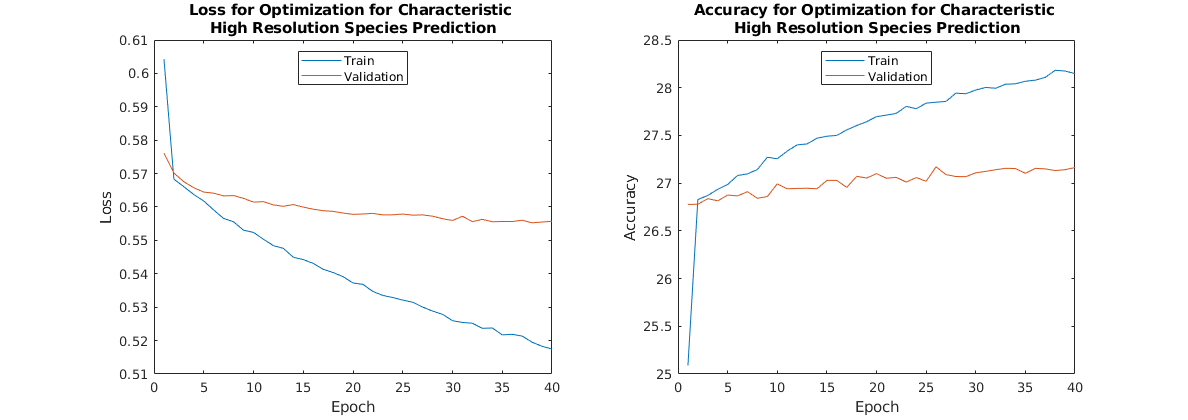

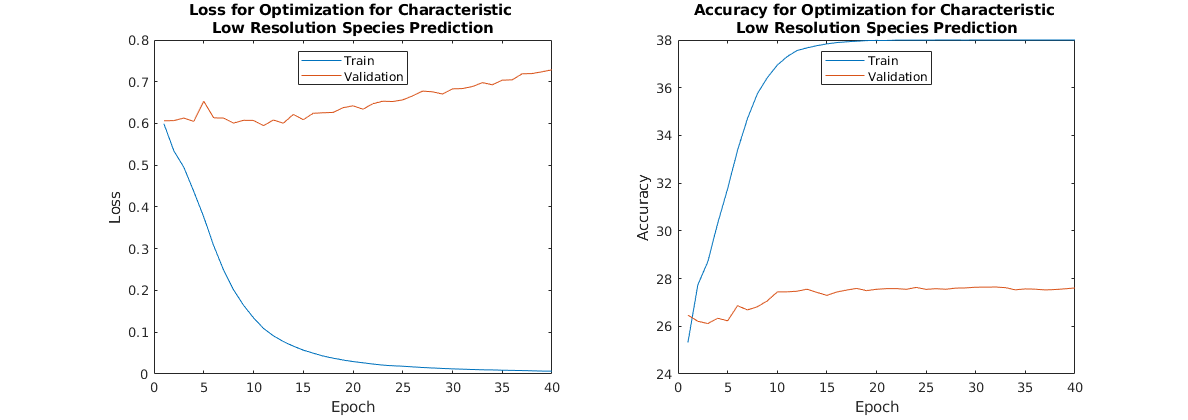

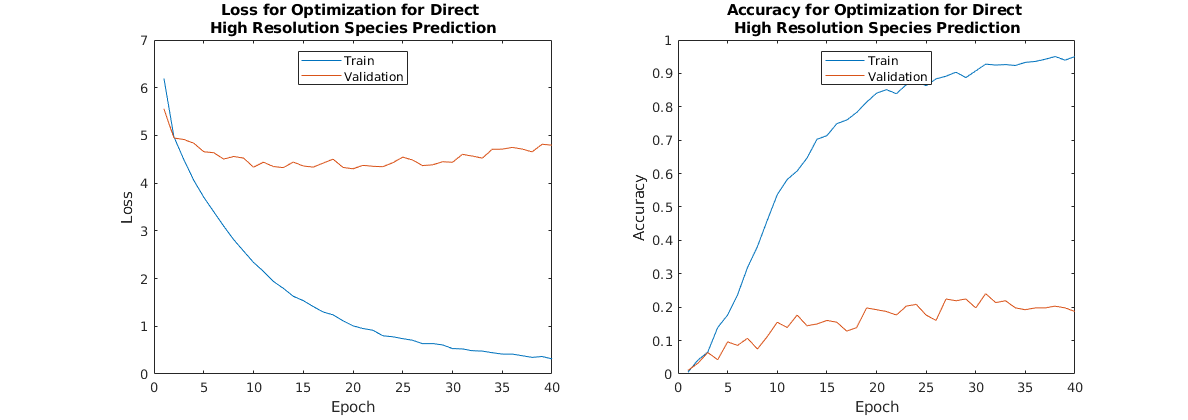

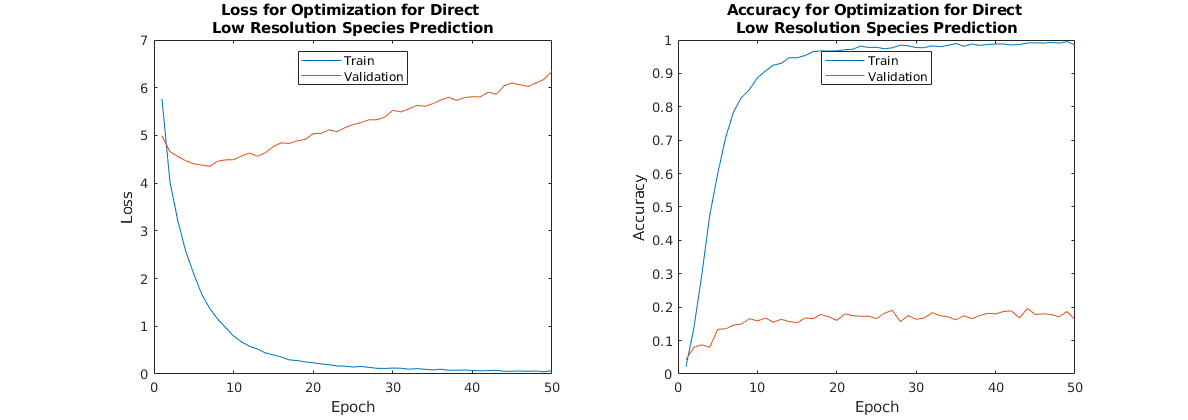

% cfiles = names(contains(names, "characteristic"))
% clen = length('characteristic');
% dfiles = names(contains(names, "direct"))
% dlen = length('direct');

for i= 1:length(names)
    f = names(i);
    t = readtable("history_data/"+f);
    fig = plotCurves(t, title_from_suffix(f));
    saveas(fig, "plots/" + replace(title_from_suffix(f), newline, "") + ".png");
end

function fig = plotCurves(t, name)
    fig = figure( "Units","normalized", "Position",[0,0,0.4,0.25]);
    subplot(1,2,1);
    plotCurve(t.train_loss, t.val_loss, name, "Loss");
    subplot(1,2,2);
    plotCurve(t.train_acc, t.val_acc, name, "Accuracy");
end
function plotCurve(train, val, name, type)
    plot(train)
    hold on
    plot(val)
    hold off
    ylabel(type)
    xlabel("Epoch")
    title(type + " for " + name)
    legend(["Train", "Validation"], "Location","north")
end
function tit = title_from_suffix(suffix)
    tit = "Optimization for ";
    suffix = string(suffix);
    if contains(suffix, "direct")
        tit = tit + "Direct ";
    else
        tit = tit + "Characteristic ";
    end
    tit = tit + newline;
    if contains(suffix, "_bolete.h5")
        tit = tit + "High Resolution";
    else
        tit = tit + "Low Resolution";
    end
    if contains(suffix, "_ed")
        tit = tit + " Edibility Prediction";
    else
        tit = tit + " Species Prediction";
    end
end